%% =========================================================
%  GEI1013 - Asservissements linéaires - Hiver 2026
%  Projet de conception - Modélisation par blocs internes
% ==========================================================
clear; clc; close all;

% PARAMÈTRES DU SYSTÈME
uB  = 24;           
Lm  = 1.577e-3;   
Rm  = 1.3;         
km  = 0.0742;     
kv  = 0.0742;      
Jr  = 1.558e-4;    
M   = 2.5;       
G   = 20;         
r   = 0.125;      
Bm  = 0.0015;      
Cf  = 300e-6;     
Lf  = 50e-6;       
Rf  = 100e3;       
k_elas = 50;

% Inertie équivalente ramenée à l'arbre moteur
Jm  = Jr + M * (r^2) / (G^2); 

%DÉFINITION DES SOUS-SYSTÈMES 
s = tf('s');
% Convertisseur de Puissance
% Fonction de transfert de commande: Uc/alpha
num_conv = uB;
den_conv = Lf*Cf*s^2 + (Lf/Rf)*s + 1;
G_conv   = num_conv / den_conv;

% Impédance de sortie du filtre : Uc/Im
num_Zconv = Lf*s;
Z_conv    = num_Zconv / den_conv;

% Le Moteur à Courant Continu
den_mot = (Lm*s + Rm)*(Jm*s + Bm) + km*kv;

%Admittance d'entrée du moteur : Im/Uc
num_Ymot = Jm*s + Bm;
Y_mot    = num_Ymot / den_mot;

%Fonction de transfert en vitesse :Wm/Uc
num_Gmot = km;
G_mot    = num_Gmot / den_mot;

%ASSEMBLAGE DES BLOCS 
G_Uc_alpha = G_conv / (1 + Z_conv * Y_mot);
G_Uc_alpha = minreal(G_Uc_alpha);

G_BO_v = G_mot * G_Uc_alpha;
G_BO_v = minreal(G_BO_v);

fprintf('=== Fonction de transfert BO (Vitesse Chariot 2)\n');

=== Fonction de transfert BO (Vitesse Chariot 2)


display(G_BO_v);


G_BO_v =
 
                         2.97e14
  -----------------------------------------------------
  s^4 + 830.3 s^3 + 6.88e07 s^2 + 5.536e10 s + 1.244e12
 
Continuous-time transfer function.


zpk(G_BO_v)


ans =
 
                  2.9702e+14
  -------------------------------------------
  (s+782) (s+23.13) (s^2 + 25.14s + 6.876e07)
 
Continuous-time zero/pole/gain model.



G_cinematique = r / (G * s);
G_BO_p = G_BO_v * G_cinematique;
G_BO_p = minreal(G_BO_p);

fprintf('=== Fonction de transfert BO (Position Chariot 1)\n');

=== Fonction de transfert BO (Position Chariot 1)


display(G_BO_p);


G_BO_p =
 
                          1.856e12
  ---------------------------------------------------------
  s^5 + 830.3 s^4 + 6.88e07 s^3 + 5.536e10 s^2 + 1.244e12 s
 
Continuous-time transfer function.


zpk(G_BO_p)


ans =
 
                   1.8564e+12
  ---------------------------------------------
  s (s+782) (s+23.13) (s^2 + 25.14s + 6.876e07)
 
Continuous-time zero/pole/gain model.



%ANALYSE DES PÔLES
disp('Pôles du système en vitesse (Actionneur 2) :');

Pôles du système en vitesse (Actionneur 2) :


disp(pole(G_BO_v));

   1.0e+03 *

  -0.0126 + 8.2922i
  -0.0126 - 8.2922i
  -0.7820 + 0.0000i
  -0.0231 + 0.0000i




disp(pole(G_BO_p));

   1.0e+03 *

   0.0000 + 0.0000i
  -0.0126 + 8.2922i
  -0.0126 - 8.2922i
  -0.7820 + 0.0000i
  -0.0231 + 0.0000i




%ANALYSE DE LA STABILITÉ VIA LES LIEUX DE RACINES
fprintf('\n=== ANALYSE DE LA STABILITÉ VIA LES LIEUX DE RACINES\n');


=== ANALYSE DE LA STABILITÉ VIA LES LIEUX DE RACINES



disp('Chariot 2');

Chariot 2


damp(G_BO_v);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.31e+01                 1.00e+00       2.31e+01         4.32e-02    
 -7.82e+02                 1.00e+00       7.82e+02         1.28e-03    
 -1.26e+01 + 8.29e+03i     1.52e-03       8.29e+03         7.95e-02    
 -1.26e+01 - 8.29e+03i     1.52e-03       8.29e+03         7.95e-02    



disp('Chariot 1');

Chariot 1


damp(G_BO_p);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -2.31e+01                 1.00e+00       2.31e+01         4.32e-02    
 -7.82e+02                 1.00e+00       7.82e+02         1.28e-03    
 -1.26e+01 + 8.29e+03i     1.52e-03       8.29e+03         7.95e-02    
 -1.26e+01 - 8.29e+03i     1.52e-03       8.29e+03         7.95e-02    


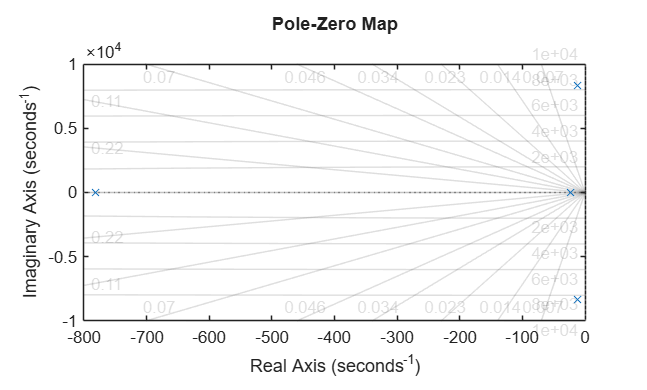


figure('Name', 'Carte des Pôles et Zéros vitesse')
pzmap(G_BO_v)
grid on

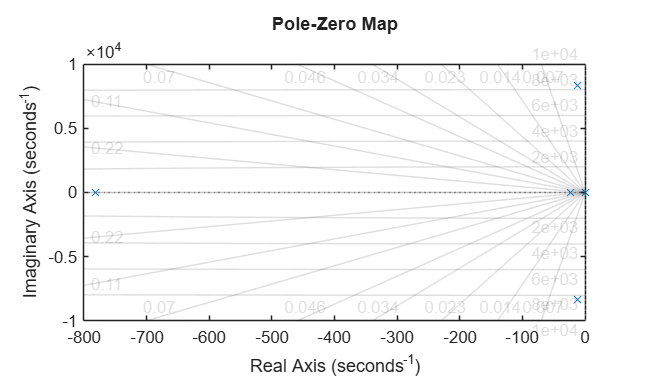


figure('Name', 'Carte des Pôles et Zéros position')
pzmap(G_BO_p)
grid on


%ANALYSE DE LA STABILITÉ via l'analyse de Bode
fprintf('\n===ANALYSE DE LA STABILITÉ via l analyse de Bode ===\n');


===ANALYSE DE LA STABILITÉ via l analyse de Bode ===



[Gm_v, Pm_v, Wcg_v, Wcp_v] = margin(G_BO_v);

fprintf('Chariot 2 (Vitesse)  : Marge Phase = %.2f deg à %.2f rad/s\n', Pm_v, Wcp_v);

Chariot 2 (Vitesse)  : Marge Phase = 3.24 deg à 8009.76 rad/s



fprintf('Marge Gain  = %.2f dB à %.2f rad/s\n', 20*log10(Gm_v), Wcg_v);

Marge Gain  = -6.47 dB à 8164.85 rad/s



[Gm_p, Pm_p, Wcg_p, Wcp_p] = margin(G_BO_p);
fprintf('Chariot 1 (Position) : Marge Phase = %.2f deg à %.2f rad/s\n', Pm_p, Wcp_p);

Chariot 1 (Position) : Marge Phase = 86.21 deg à 1.49 rad/s


fprintf('Marge Gain  = %.2f dB à %.2f rad/s\n', 20*log10(Gm_p), Wcg_p);

Marge Gain  = 54.63 dB à 134.46 rad/s


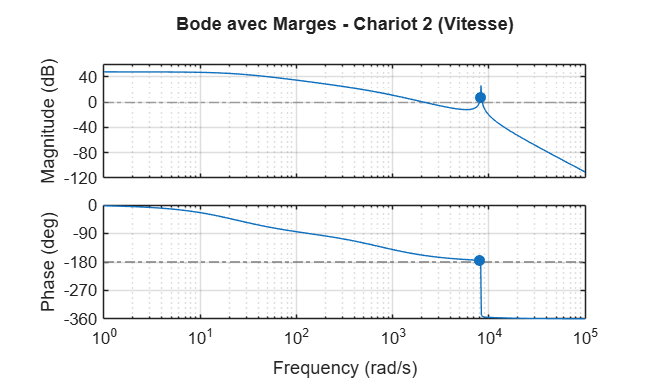


figure('Name', 'Diagrammes de Bode (Boucle Ouverte)');
margin(G_BO_v);
title('Bode avec Marges - Chariot 2 (Vitesse)');
grid on;

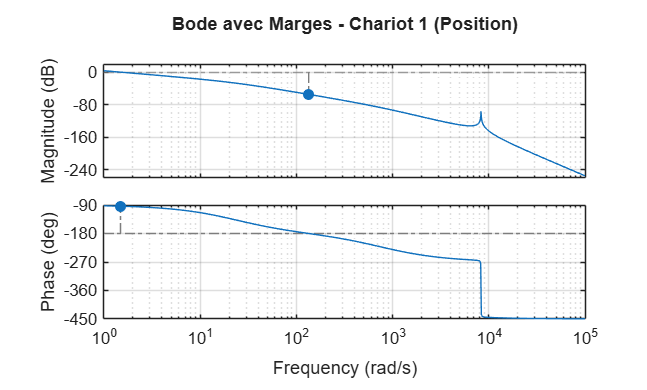


figure('Name', 'Diagrammes de Bode (Boucle Ouverte)');
margin(G_BO_p);
title('Bode avec Marges - Chariot 1 (Position)');
grid on;


%ANALYSE TEMPORELLE
fprintf('\n=== ANALYSE TEMPORELLE\n');


=== ANALYSE TEMPORELLE



Kp_v = dcgain(G_BO_v); 
erreur_stat_v = 1 / (1 + Kp_v);
fprintf('Chariot 2 (Vitesse)  : Classe = 0 | Gain Kp = %.4f | Erreur échelon unitaire = %.2f %%\n', Kp_v, erreur_stat_v * 100);

Chariot 2 (Vitesse)  : Classe = 0 | Gain Kp = 238.8527 | Erreur échelon unitaire = 0.42 %



s = tf('s');
Kv_p = dcgain(s * G_BO_p);
fprintf('Chariot 1 (Position) : Classe = 1 | Gain Kv = %.4f | Erreur de traînage = %.4f unités\n', Kv_p, 1/Kv_p);

Chariot 1 (Position) : Classe = 1 | Gain Kv = 1.4928 | Erreur de traînage = 0.6699 unités


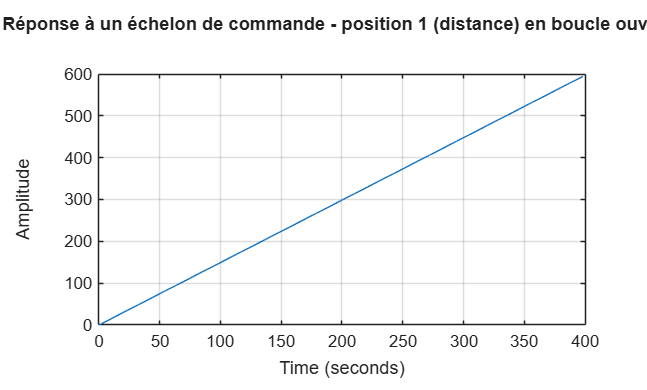


% Visualisation de la réponse temporelle (Boucle ouverte)
figure('Name', 'Réponse indicielle (Échelon unitaire en BO)', 'NumberTitle', 'off');
step(G_BO_p);
title('Réponse à un échelon de commande - position 1 (distance) en boucle ouverte');
grid on;

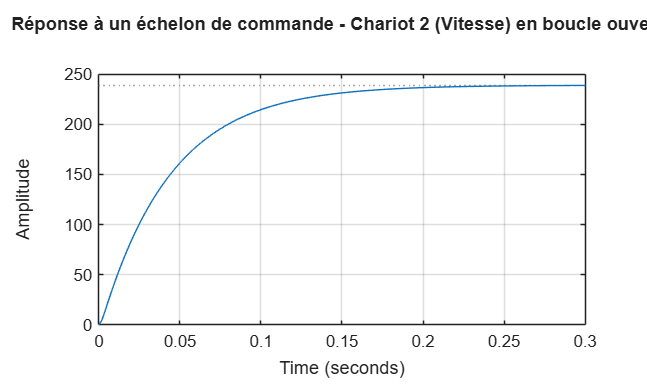


figure('Name', 'Réponse indicielle (Échelon unitaire en BO)', 'NumberTitle', 'off');
step(G_BO_v);
title('Réponse à un échelon de commande - Chariot 2 (Vitesse) en boucle ouverte');
grid on;

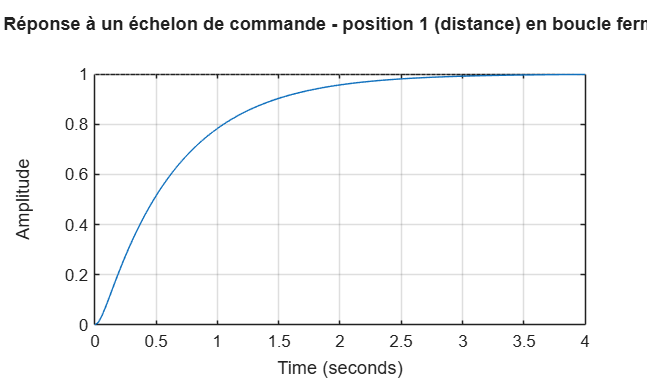

% Visualisation de la réponse temporelle (Boucle fermeé)
figure('Name', 'Réponse indicielle (Échelon unitaire en BF)', 'NumberTitle', 'off');
step(feedback(G_BO_p , 1) );
title('Réponse à un échelon de commande - position 1 (distance) en boucle fermée');
grid on;

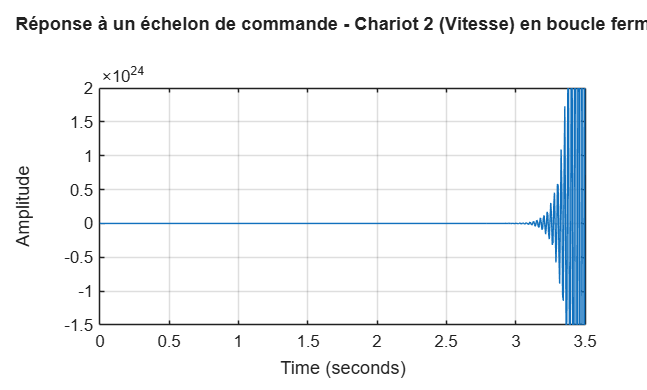


figure('Name', 'Réponse indicielle (Échelon unitaire en BF)', 'NumberTitle', 'off');
step(feedback(G_BO_v , 1));
title('Réponse à un échelon de commande - Chariot 2 (Vitesse) en boucle fermée');
grid on;

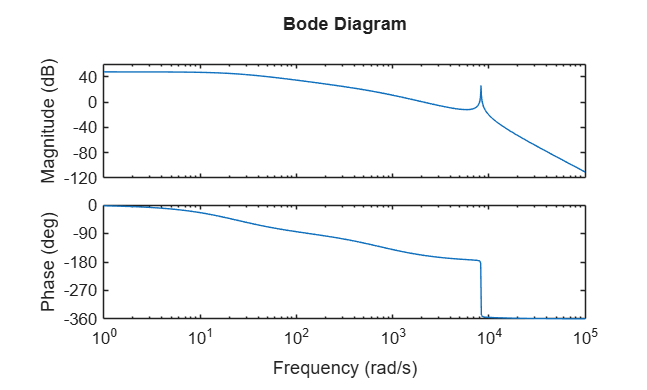


figure('Name','Boucle ouverte vitesse')
bode(G_BO_v)

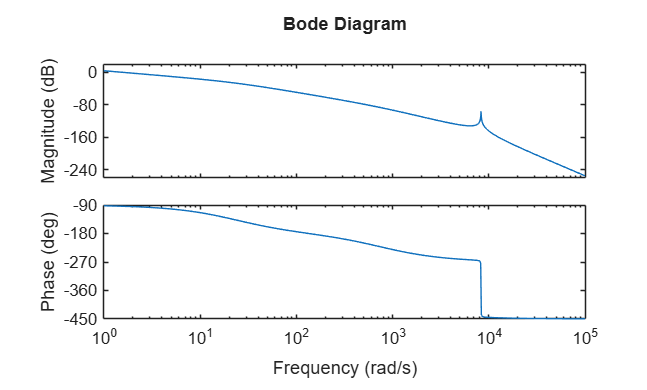

figure('Name','Boucle ouverte position')
bode(G_BO_p)

%  SYNTHÈSE DU COMPENSATEUR D'AVANCE AVEC INTÉGRATEUR (Vitesse)
fprintf('\n=== CONCEPTION DU CORRECTEUR DE VITESSE ===\n');


=== CONCEPTION DU CORRECTEUR DE VITESSE ===



% Spécifications
wcp_star = 50;         
phi_m_visee = 50;          

%Évaluation du système non corrigé
[mag_val, phase_val] = bode(G_BO_v, wcp_star);
mag_val = squeeze(mag_val);     
phase_val = squeeze(phase_val); 

fprintf('À wcp = %d rad/s, le système naturel a un gain de %.4e et une phase de %.2f deg.\n', ...
    wcp_star, mag_val, phase_val);

À wcp = 50 rad/s, le système naturel a un gain de 1.0007e+02 et une phase de -68.84 deg.



phi_max = phi_m_visee - 90 - phase_val ;
fprintf('Avance de phase maximale requise (phi_max) : %.2f deg\n', phi_max);

Avance de phase maximale requise (phi_max) : 28.84 deg



if phi_max > 65
    warning('L''avance de phase requise dépasse 65 degrés. La valeur de alpha risque d''être trop faible (amplification excessive du bruit).');
end

alpha = (1 - sind(phi_max)) / (1 + sind(phi_max));
T = 1 / (wcp_star * sqrt(alpha));

K = wcp_star * sqrt(alpha) / mag_val;

fprintf('\n=== Paramètres du correcteur ===\n');


=== Paramètres du correcteur ===


fprintf('K     = %.4e\n', K);

K     = 2.9528e-01


fprintf('alpha = %.4f\n', alpha);

alpha = 0.3492


fprintf('T     = %.6e s\n', T);

T     = 3.384389e-02 s



% Construction de la fonction de transfert du correcteur C2(s)
s = tf('s');
Integrateur = K / s;
Reseau_Avance = (T * s + 1) / (alpha * T * s + 1);
C2_vitesse = Integrateur * Reseau_Avance;

fprintf('\nFonction de transfert du Correcteur C2(s) :\n');


Fonction de transfert du Correcteur C2(s) :


C2_vitesse = minreal(C2_vitesse);
display(C2_vitesse);


C2_vitesse =
 
  0.8455 s + 24.98
  ----------------
   s^2 + 84.61 s
 
Continuous-time transfer function.



% VALIDATION EN BOUCLE FERMÉE (Vitesse)
fprintf('\n=== VALIDATION DES PERFORMANCES (Vitesse) ===\n');


=== VALIDATION DES PERFORMANCES (Vitesse) ===



% Calcul de la nouvelle boucle ouverte corrigée
L_vitesse = C2_vitesse * G_BO_v;

% Vérification des marges
[Gm_new, Pm_new, Wcg_new, Wcp_new] = margin(L_vitesse);
fprintf('Nouvelle Marge de Phase = %.2f deg à %.2f rad/s\n', Pm_new, Wcp_new);

Nouvelle Marge de Phase = 50.00 deg à 50.00 rad/s


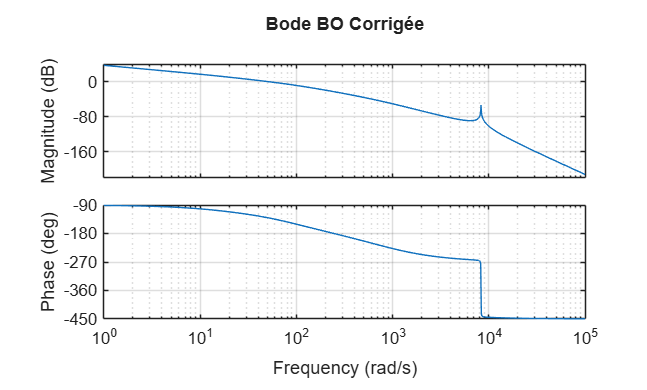


% Fermeture de la boucle unitaire
T_vitesse = feedback(L_vitesse, 1);

% Tracés
figure('Name', 'Validation du Correcteur de Vitesse en boucle ouverte', 'NumberTitle', 'off');
bode(L_vitesse);
title('Bode BO Corrigée');
grid on;

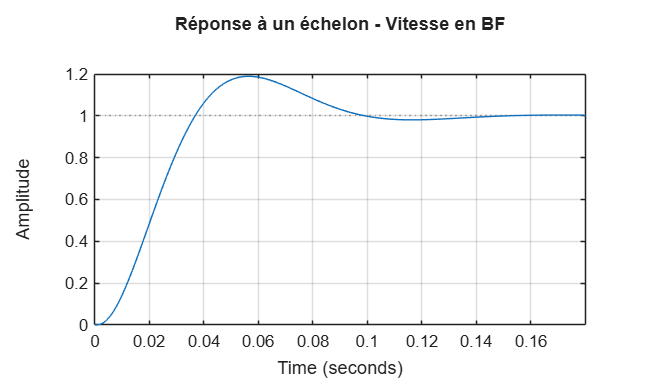


figure('Name', 'Validation du Correcteur de Vitesse en boucle fermée', 'NumberTitle', 'off');
step(T_vitesse);
title('Réponse à un échelon - Vitesse en BF');
grid on;


info_step = stepinfo(T_vitesse);
fprintf('Dépassement (Overshoot) : %.2f %%\n', info_step.Overshoot);

Dépassement (Overshoot) : 18.89 %


fprintf('Temps de réponse (5%%)  : %.4f s\n', info_step.SettlingTime);

Temps de réponse (5%)  : 0.0928 s


%  10. SYNTHÈSE DU COMPENSATEUR D'AVANCE (Position Chariot 1)
fprintf('\n=== CONCEPTION DU CORRECTEUR DE POSITION \n');


=== CONCEPTION DU CORRECTEUR DE POSITION 



% Spécifications
wcp_p_star = 15;        
phi_m_p_visee = 50;    

% Évaluation du système 
[mag_p, phase_p] = bode(G_BO_p, wcp_p_star);
mag_p = squeeze(mag_p);     
phase_p = squeeze(phase_p); 

fprintf('À wcp = %d rad/s, le système naturel a un gain de %.4e et une phase de %.2f deg.\n', ...
    wcp_p_star, mag_p, phase_p);

À wcp = 15 rad/s, le système naturel a un gain de 8.3481e-02 et une phase de -124.07 deg.



phi_max_p = phi_m_p_visee - 180 - phase_p ;

% Vérification si une avance est réellement nécessaire
if phi_max_p < 0
    fprintf('Le système naturel a déjà assez de phase. Un simple gain proportionnel (P) suffirait.\n');
    phi_max_p = 0;
    alpha_p = 1;
    T_p = 0;
    K_p = 1 / mag_p;
else
    fprintf('Avance de phase maximale requise (phi_max) : %.2f deg\n', phi_max_p);
    
    %Calcul des paramètres
    alpha_p = (1 - sind(phi_max_p)) / (1 + sind(phi_max_p));
    T_p = 1 / (wcp_p_star * sqrt(alpha_p));
    
    % Calcul du gain K
    K_p = sqrt(alpha_p) / mag_p;
end

Le système naturel a déjà assez de phase. Un simple gain proportionnel (P) suffirait.



fprintf('\n=== Paramètres analytiques du correcteur ===\n');


=== Paramètres analytiques du correcteur ===


fprintf('K     = %.4e\n', K_p);

K     = 1.1979e+01


fprintf('alpha = %.4f\n', alpha_p);

alpha = 1.0000


fprintf('T     = %.6e s\n', T_p);

T     = 0.000000e+00 s



% Construction de C1(s)
s = tf('s');
C1_position = K_p * (T_p * s + 1) / (alpha_p * T_p * s + 1);
C1_position


C1_position =
 
  11.98
 
Static gain.


fprintf('\nFonction de transfert du Correcteur C1(s) :\n');


Fonction de transfert du Correcteur C1(s) :


C1_position = minreal(C1_position);
display(C1_position);


C1_position =
 
  11.98
 
Static gain.



% VALIDATION EN BOUCLE FERMÉE (Position)
fprintf('\n=== VALIDATION DES PERFORMANCES (Position) ===\n');


=== VALIDATION DES PERFORMANCES (Position) ===



L_position = C1_position * G_BO_p;
[Gm_p_new, Pm_p_new, Wcg_p_new, Wcp_p_new] = margin(L_position);
fprintf('Nouvelle Marge de Phase = %.2f deg à %.2f rad/s\n', Pm_p_new, Wcp_p_new);

Nouvelle Marge de Phase = 55.93 deg à 15.00 rad/s


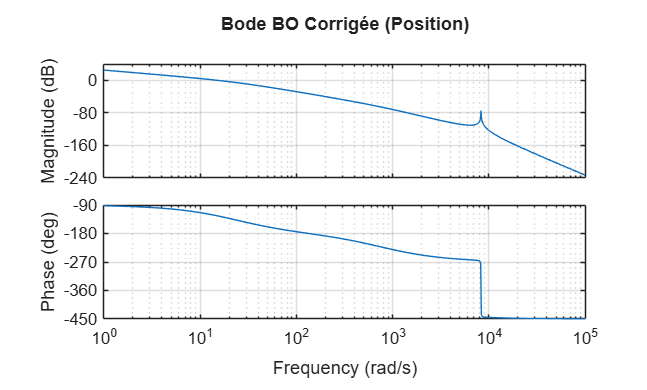


T_position = feedback(L_position, 1);

figure('Name', 'Validation du Correcteur de Position en boucle ouverte', 'NumberTitle', 'off');
bode(L_position);
title('Bode BO Corrigée (Position)');
grid on;

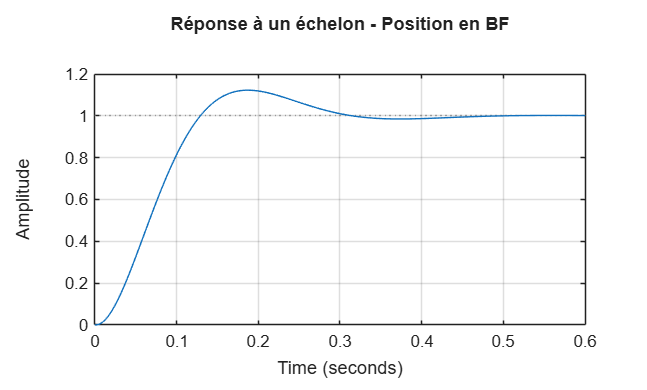


figure('Name', 'Validation du Correcteur de Position en boucle fermée', 'NumberTitle', 'off');
step(T_position);
title('Réponse à un échelon - Position en BF');
grid on;


info_step_p = stepinfo(T_position);
fprintf('Dépassement (Overshoot) : %.2f %%\n', info_step_p.Overshoot);

Dépassement (Overshoot) : 12.26 %


fprintf('Temps de réponse (5%%)  : %.4f s\n', info_step_p.SettlingTime);

Temps de réponse (5%)  : 0.2888 s


%  12. SYNTHÈSE DU CORRECTEUR INTÉGRAL (Force de la bande élastique)
fprintf('\n=== CONCEPTION DU CORRECTEUR DE FORCE (BOUCLE EXTERNE) ===\n');


=== CONCEPTION DU CORRECTEUR DE FORCE (BOUCLE EXTERNE) ===


G_sys3 = k_elas * T_position;
G_sys3


G_sys3 =
 
                                1.112e15
  --------------------------------------------------------------------
  s^5 + 830.3 s^4 + 6.88e07 s^3 + 5.536e10 s^2 + 1.244e12 s + 2.224e13
 
Continuous-time transfer function.


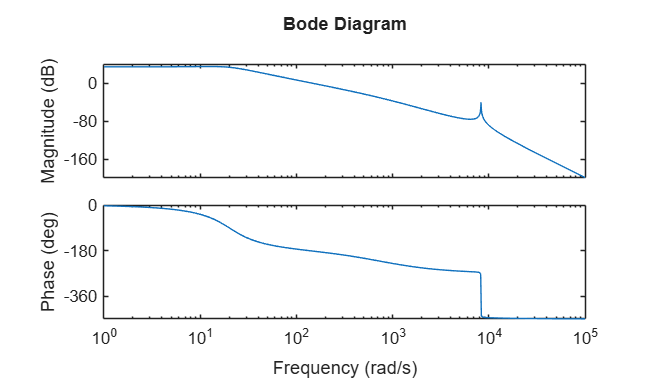

bode(G_sys3)
margin(G_sys3)

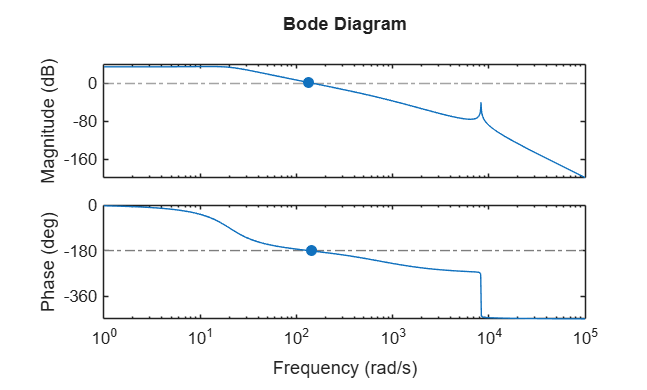

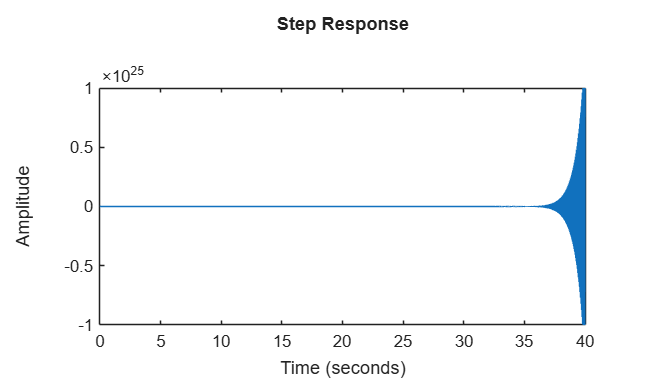

step(feedback(G_sys3,1))

wcp3_star = 2.5;        

[mag3, phase3] = bode(G_sys3, wcp3_star);
mag3 = squeeze(mag3);

fprintf('À wcp = %.1f rad/s, le système a un gain de %.4f.\n', wcp3_star, mag3);

À wcp = 2.5 rad/s, le système a un gain de 50.2861.



K_i = wcp3_star / mag3;

fprintf('\n=== Paramètres analytiques du correcteur I ===\n');


=== Paramètres analytiques du correcteur I ===


fprintf('K_i = %.4e\n', K_i);

K_i = 4.9716e-02



s = tf('s');
C3_force = K_i / s;

fprintf('\nFonction de transfert du Correcteur C3(s) :\n');


Fonction de transfert du Correcteur C3(s) :


display(C3_force);


C3_force =
 
  0.04972
  -------
     s
 
Continuous-time transfer function.



%  13. VALIDATION EN BOUCLE FERMÉE (Force)
fprintf('\n=== VALIDATION DES PERFORMANCES (Force) ===\n');


=== VALIDATION DES PERFORMANCES (Force) ===



L_force = C3_force * G_sys3;
[Gm_f, Pm_f, Wcg_f, Wcp_f] = margin(L_force);
fprintf('Nouvelle Marge de Phase = %.2f deg à %.2f rad/s\n', Pm_f, Wcp_f);

Nouvelle Marge de Phase = 81.92 deg à 2.50 rad/s


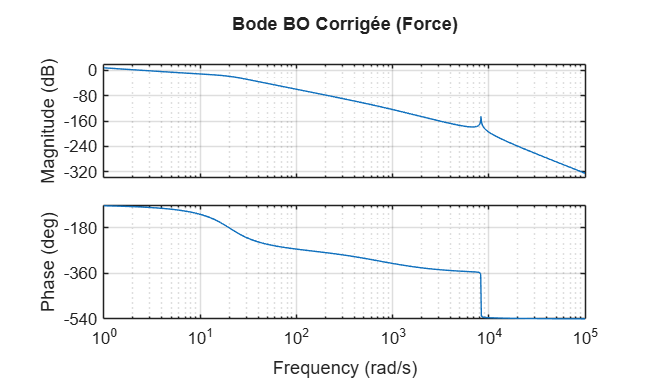


T_force = feedback(L_force, 1);

figure('Name', 'Validation du Correcteur de Force en boucle ouverte', 'NumberTitle', 'off');
bode(L_force);
title('Bode BO Corrigée (Force)');
grid on;

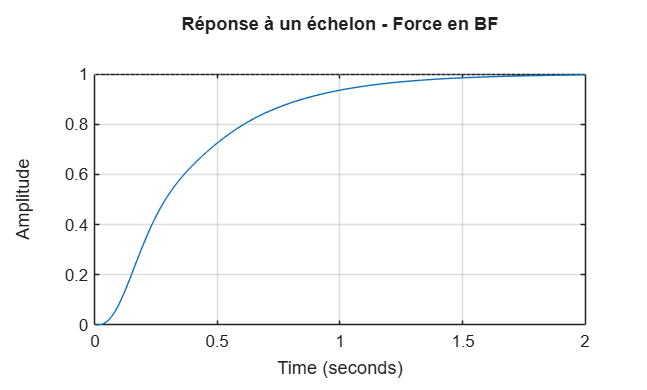


figure('Name', 'Validation du Correcteur de Force en boucle fermée', 'NumberTitle', 'off');
step(T_force);
title('Réponse à un échelon - Force en BF');
grid on;


info_step_f = stepinfo(T_force);
fprintf('Dépassement (Overshoot) : %.2f %%\n', info_step_f.Overshoot);

Dépassement (Overshoot) : 0.00 %


fprintf('Temps de réponse (5%%)  : %.4f s\n', info_step_f.SettlingTime);

Temps de réponse (5%)  : 1.4039 s
